# Fresnel equations

[EE551-Spring 2021-Tutorial 1-Fresnel Equations ](https://github.com/SrikanthS-IIT/EE551-Tutorials-Spring2021/blob/main/EE551-Spring2021-Tutorial1_FresnelEquations.mlx)by [Srikanth Sugavanam ](https://www.srikanthsugavanam.com/)is licensed under [CC BY-NC 4.0    ](https://creativecommons.org/licenses/by-nc/4.0?ref=chooser-v1)

In this tutorial, we will explore the Fresnel equations that relate the incident, reflected and transmitted components of light at an interface.

*Learning outcomes - *

- Analyze the reflection and transmission coefficients for orthogonal polarizations of the incident field.

- Evaluate the influence of the complex nature of the reflection and transmission coefficients.

- Distinguish between their characteristics when the incident and transmitted media are interchanged.

There are four tasks in this tutorial, the fifth task being left as an optional exercise. The solution for the case when the electric field is perpendicular to the plane of incidence is solved as an example. 

## The equations

The Fresnel equations relate the amplitude and phases of the reflected and refracted light waves incident on a medium. There are four Fresnel equations, two each for the E-field of light parallel to, and perpendicular to the plane of incidence. 

For light perpendicular to the plane of incidence, the reflection and transmission coefficients are given by 

$r_{\bot } =\frac{n_i \cos \theta_i -n_t \cos \theta_t }{n_i \cos \theta_i +n_t \cos \theta_t }$, and $t_{\bot \;} =\frac{\;2n_i \cos \theta_i }{n_i \cos \theta_i +n_t \cos \theta_t }$.

For light parallel to the plane of incidence, the reflection and transmission coefficients are given by

$r_{\parallel } =\frac{n_t \cos \theta_i -n_i \cos \theta_t \;}{n_t \cos \theta_i +n_i \cos \theta_t }$, and $t_{\parallel \;} =\frac{\;2n_i \cos \theta_i }{n_t \cos \theta_i +n_i \cos \theta_t }$.

Here, the subscripts $i,t$ refer to quantities in the incident and transmitted media respectively. 

## Light travelling from a rarer medium to a denser medium

We will first consider the case of light travelling from a rarer medium to a denser medium. In this case, $n_i <n_t$. We will now plot the coefficients as a function of the incident angle $\theta_i$. We should then arrive at a graph which looks like

### Calculating the transmitted angle

All the Fresnel equations are a function of both the incident and the transmitted angle. The incident angle $\theta_{i\;}$is an independent variable, while the Snell's law can be used to calculate the transmitted (refracted) angle. 

We first define the range of $\theta_i$ values and the refractive indices:

theta_i = 0:0.1:90; %theta_i is in degrees.
ni = 1;
nt = 1.5;

Snell's law is given as


$$n_i \sin \theta_i =n_t \sin \theta_t \;$$


or, $\theta_t =\sin^{-1} \left(n_i \sin \theta_i /n_t \right)\ldotp \;$

So we can calculate the values of $\theta_t$ values as:

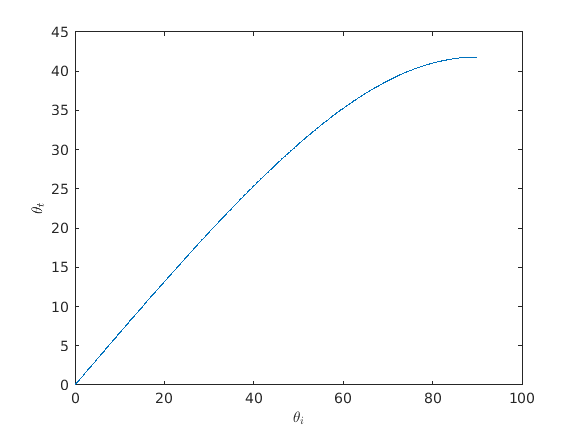

theta_t = asind(ni*sind(theta_i)/nt);
plot(theta_i,theta_t);
xlabel('$\theta_i$',"interpreter","latex");
ylabel('$\theta_t$',"interpreter","latex");

We now have the range of incident and transmitted angles, so we can directly plug them into the Fresnel equations.

### Fresnel equations for electric field perpendicular to the plane of incidence

We will now plot the dependence of $r_{\bot \;}$and $t_{\bot \;}$with $\theta_i$. First we calculate these values as follows (the 'p' stands for $\bot \;$) :

rp = (ni*cosd(theta_i) - nt*cosd(theta_t))./(ni*cosd(theta_i)+nt*cosd(theta_t));
tp = (2*ni*cosd(theta_i))./(ni*cosd(theta_i)+nt*cosd(theta_t));

%Note the use of the dot operator '.' when dividing the vector/array
%quantities theta_i and theta_t.

In general these coefficients can be treated as complex quantities. That is, 

$r_{\bot \;} ={\left(r_{\bot \;} \right)}_0 \exp \left(i\phi {\;}_{r_{\bot \;} } \right)$, and $t_{\bot \;} ={\left(t_{\bot \;} \right)}_0 \exp \left(i\phi_{t_{\bot \;} } \right)$.

Then the absolute part of the coefficients can be seen as influencing as purely the amplitude of the field, while the argument can be seen to contribute to a phase advance or retardance. So, we will plot a total of four quantities - the absolute values of the coefficients, and their arguments. 

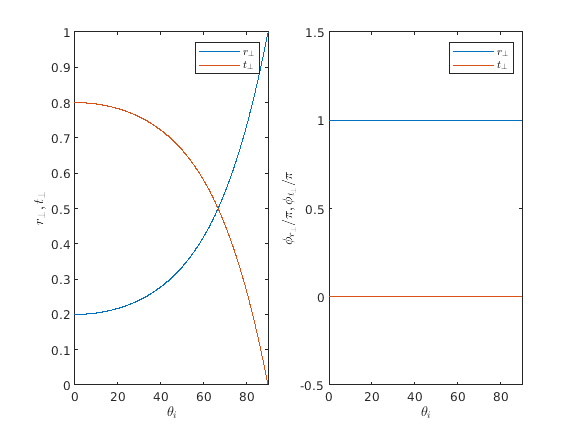

abs_rp = abs(rp);
abs_tp = abs(tp);

arg_rp = angle(rp);
arg_tp = angle(tp);

subplot(1,2,1);
plot(theta_i,abs_rp,theta_i,abs_tp);
xlim([0,90]);
xlabel("$\theta_i$","Interpreter","latex")
ylabel("$r_\bot, t_\bot$","Interpreter","latex")
legend("$r_\bot$","$t_\bot$","Interpreter", "latex")
subplot(1,2,2);
plot(theta_i,(arg_rp)/pi,theta_i,(arg_tp)/pi);
xlim([0,90]);
xlabel("$\theta_i$","Interpreter","latex")
ylabel("$\phi_{r_\bot}/\pi, \phi_{t_\bot}/\pi$","Interpreter","latex")
legend("$r_\bot$","$t_\bot$","Interpreter", "latex")
ylim([-0.5 1.5])

We can understand the above graphs as follows - for normal incidence ($\theta_i =0$), most of the light is transmitted into the medium, with a small part being reflected backwards. However, as we proceed to larger values of $\theta_i$, most of the light is actually reflected back to the incident medium, so much so that at grazing incidence ($\theta_i ~{90}^0$), the interface behaves like a perfect reflector!

We further see that while $\phi_{t_{\bot \;} } =0$ for all values of $\theta_i$, $\phi_{r_{\bot \;} } =\pi$. This means that light undergoes a phase reversal of $\pi$ when it is reflected off from a denser medium. No such phase change is observed for the transmitted light. 

### Task 1 - Fresnel equations for electric field parallel to the plane of incidence

Following the above example for $r_{\bot \;}$and $t_{\bot \;}$plot the absolute values and arguments of $r_{\parallel }$ and $t_{\parallel }$ below.

Once you have the following, investigate the following - 

- What are the values of the coefficients for $\theta_i =0$? Are they the same as you obtained for $r_{\bot \;}$and $t_{\bot \;}$? If so, why do you think this is the case?

- How is the absolute value of $r_{\parallel }$ different from that of $r_{\bot \;}$?

- How is the phase $\phi_{r_{\parallel } }$ different from $\phi_{r_{\bot \;} }$?

### Task 2 - Reflectance and Transmittance

The expressions for the reflectance$R$ and transmittance$T$, i.e. the actual fraction of radiant energies reflected and transmitted at an interface is given by 

$R=r^2$, and $T=\left(\frac{n_t \cos \theta_t }{n_i \cos \theta_{i\;} }\right)t^2$. (See p127, Optics, 4e, Hecht).

Do the following - 

- Plot $R_{\bot \;}$and $T_{\bot \;}$as a function of $\theta_i$ in one graph.

- Plot $R_{\parallel \;}$and $T_{\parallel \;}$as a function of $\theta_i$ in one graph.

- Verify the expressions obey the principle of conservatoin of energy.

## Light travelling from a denser medium to a rarer medium

Now, we flip the direction of light, and see how the Fresnel equations predict its behaviour. As we shall see, it is not as straightforward as simply interchanging the values of ni and nt and running our code above. The problems start right from the beginning. 

ni = 1.5;
nt = 1.0;

### Calculating the transmittance angle

We can again use the Snell's law - but this time we will first plot $\sin \theta_t$ vs. $\theta_i$. 

***What is wrong?***

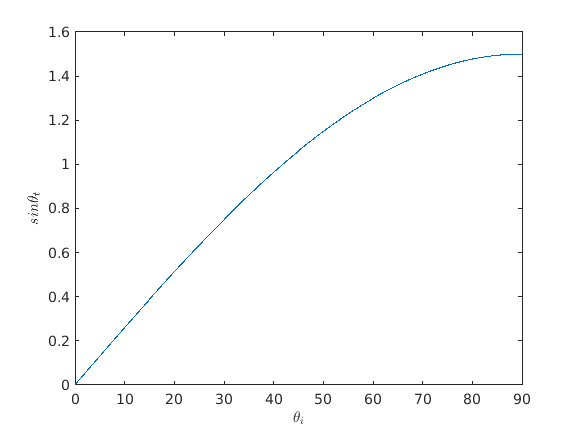

sin_theta_t = (ni*sind(theta_i)/nt);
figure;
plot(theta_i,sin_theta_t);
xlabel('$\theta_i$',"interpreter","latex");
ylabel('$sin\theta_t$',"interpreter","latex");
xlim([0 90]);
ylim([0 1.6]);

### Task 3 - Critical angle

The critical angle of incidence is that for which the angle of transmittance is ${90}^0$. Calculate the critical angle from the graph above. 

### Recasting the Fresnel equations

Note that the Snell's law was arrived at without making any special assumptions. This means that this relation holds regardless of the configuration of the media. To avoid complications of calculating the sine of quantities greater than 1 (it is possible, the result will be a complex number), we will just recast the Fresnel equations such that its dependence on $\theta_t \;$is removed, and it is completely expressed as a function of $\theta_i$. Using basic trigonometric identities and Snell's law, we can write (see Optics, 4e, Hecht).

$r_{\bot \;} =\frac{\mathrm{cos}\theta_i -{\left(n_{\mathrm{ti}}^{2\;} -{\mathrm{sin}}^2 \theta_i \right)}^{1/2} }{\mathrm{cos}\theta_i +{\left(n_{\mathrm{ti}}^2 -{\mathrm{sin}}^2 \theta_i \right)}^{1/2} }$, and $r_{\parallel } =\frac{n_{\mathrm{ti}}^2 \mathrm{cos}\theta_i -{\left(n_{\mathrm{ti}}^{2\;} -{\mathrm{sin}}^2 \theta_i \right)}^{1/2} \;}{n_{\mathrm{ti}}^2 \mathrm{cos}\theta_i +{\left(n_{\mathrm{ti}}^{2\;} -{\mathrm{sin}}^2 \theta_i \right)}^{1/2} }$.

Here, $n_{\mathrm{ti}} =\frac{n_t }{n_i }$. From here, we can see directly that we are dealing with complex values for the reflection coefficients. 

### Task 4 - Fresnel reflection coefficients for denser-to-rarer medium propagation

Like in Task 1, plot the dependence of the absolute value and arguments of $r_{\bot \;}$and $r_{\parallel }$ on the angle of incidence $\theta_{i\;}$.

- Verify the correctness of your code by putting ni = 1.0 and nt = 1.5. The plots should be identical to those obtained in Task 1.

- Do any of the reflection coefficients go to zero? If it does, at what angle does it go to zero?

- How do the phases of the reflection coefficients behave?

- Verify if the critical angle you obtained in Task 3 is the same to that indicated by the reflection coefficients. 

- What is the relative phase between the reflection coefficients?* (we will revisit this in a later class).

### Optional - Task 5 - Fresnel transmission coefficients for denser-to-rarer medium propagation

- Recast the Fresnel equations for the transmission coefficients in terms of the incident angle $\theta_i$, and plot its absolute values and arguments w.r.t $\theta_i$.

- Plot the reflectance and transmittance curves, and verify that they satisfy the principle of conservation of energy. 

## References

Hecht, E., "Optics", 4e, Pearson Education, 2005.